# **Task_02a:**   Conduct an Impact test and log the simulation I/O

For our single floor tower model, we will:

- Keep the ground **stationary** 

- Apply an impact load FORCE in the **Horizontal**(X-dir)** direction** to the floor of the building

- Log both the applied FORCE and the floor's DISPLACEMENT  (X-direction) response

- The timeseries data will be logged to an **EXCEL** file named `bh_IMPACT_TEST.xlsx`

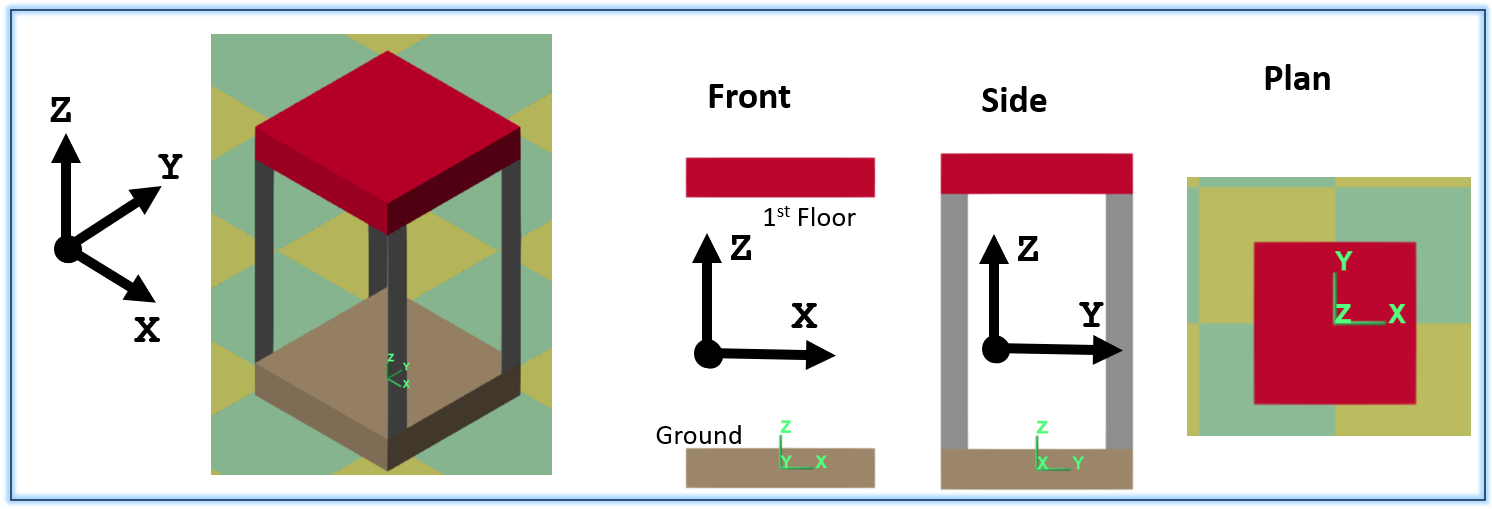

## Clear the workspace

clear

## Load the STANDARD params

- see the script [`STANDARD_params_single_tower.mlx`](matlab:  open STANDARD_params_single_tower.mlx)

STANDARD_params_single_tower

whos

  Name               Size            Bytes  Class                       Attributes

  col_OBJ            1x1               286  bh_flex_column_CLS                    
  earth_vis_OBJ      1x1                72  earth_vis_CLS                         
  floor_OBJ          1x1                32  bh_solid_floor_CLS                    
  params_dB          1x1              9689  bh_flex_tower_params_CLS              



## Configure for this TEST

Define column damping

col_OBJ.damp_ratio = 5e-3;  %1e-1;  %params_dB.col_damp_ratio;

Define the number of elements in each COLUMN

- NOTE: we will stick to the DEFAULT of just one element per column

% col_OBJ.num_eles      = 5;

OK so what have we got

col_OBJ

col_OBJ =   bh_flex_column_CLS with properties:

          WIDTH_x: 3.5000e-04
          DEPTH_y: 0.0170
         LENGTH_z: 0.1600
          density: 7900
      E_GPa_Young: 170
        v_Poisson: 0.3000
     damp_M_coeff: 0
     damp_K_coeff: 1.0000e-03
       damp_ratio: 0.0050
         num_eles: 1
    num_ret_modes: 5
          BC_case: "FIXED_FIXED_WITH_SWAY"
             mass: 0.0075
              vol: 9.5200e-07
               Ix: 1.4330e-10
               Iy: 6.0740e-14
               Kx: 30.2512
             area: 5.9500e-06


## Run the Simulink model

When the Simulink model opens .... run it.

- The FORCE and RESPONSE timeseries data will be logged to an EXCEL file named `bh_IMPACT_TEST.xlsx`

open_system("bh_single_tower_IMPACT_excitation_test.slx")

After collecting the FORCE and RESPONSE measurement data from the Simulation ... we'll analyze it NEXT ... and extract Modal properties.